% (exp(x)*sin(y)+x)*dx+(exp(x)*cos(y)+y)*dy=0

clear
% 1)
% y'=-(exp(x)*sin(y)+x)/(exp(x)*cos(y)+y)
syms x y(x)
eqn=diff(y(x))==-(exp(x)*sin(y)+x)/(exp(x)*cos(y)+y)

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{x+\sin\left(y\left(x\right)\right)\,{\mathrm{e}}^{x}}{y\left(x\right)+\cos\left(y\left(x\right)\right)\,{\mathrm{e}}^{x}}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(2\,{\mathrm{e}}^{x}\,\sin\left(y\right)+y^{2}=-x^{2}-2\,C_{4},y\right)$$

% solve(2*exp(x)*sin(y) + y^2 == - x^2 - 2*C14, y)
% 2*exp(x)*sin(y) + y^2 + x^2 = C

% 2)
syms x y
P(x,y)=exp(x)*sin(y)+x

$$P(x, y) = x+{\mathrm{e}}^{x}\,\sin\left(y\right)$$

Q(x,y)=exp(x)*cos(y)+y

$$Q(x, y) = y+{\mathrm{e}}^{x}\,\cos\left(y\right)$$

f=diff(P,y)-diff(Q,x)

$$f(x, y) = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P(x,y),x)+C(y)

$$U = C\left(y\right)+{\mathrm{e}}^{x}\,\sin\left(y\right)+\frac{x^{2}}{2}$$

% C(y) + exp(x)*sin(y) + x^2/2
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)+{\mathrm{e}}^{x}\,\cos\left(y\right)$$

% diff(C(y), y) + exp(x)*cos(y)
dCy=simplify(dUy-Q)

$$dCy(x, y) = \frac{\partial }{\partial y}C\left(y\right)-y$$

% diff(C(y), y) - y
C(y)=int(y,y)

$$C(y) = \frac{y^{2}}{2}$$

% y^2/2
% 2*exp(x)*sin(y) + x^2 + y^2 = C

% 3)
x0=0;y0=0;
U=simplify(int(P(x,y),x,x0,x)+int(subs(Q(x,y),x,x0),y,y0,y))

$$U = {\mathrm{e}}^{x}\,\sin\left(y\right)+\frac{x^{2}}{2}+\frac{y^{2}}{2}$$

syms C
eq2=2*U==C

$$eq2 = 2\,{\mathrm{e}}^{x}\,\sin\left(y\right)+x^{2}+y^{2}=C$$

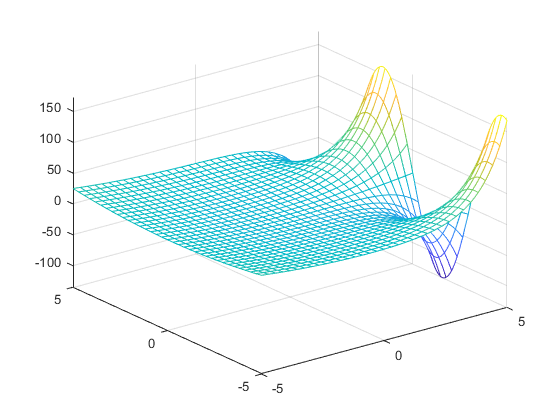

fmesh(U)